1

syms n
an = (n^3 + 2*n^2 + 1) / (n^3 + n^2 + n + 1);
limit_an = limit(an, n, inf);
disp(limit_an);

$$1$$

2

syms x y;
f = x^3 * y^2 * exp(-x * y);
df_dx = diff(f, x);
df_dy = diff(f, y);
df_dx_at_1_2 = subs(df_dx, [x, y], [1, 2]);
df_dy_at_1_2 = subs(df_dy, [x, y], [1, 2]);
disp('在點 (1, 2) 處，對 x 的偏導數為:');

在點 (1, 2) 處，對 x 的偏導數為:


disp(df_dx_at_1_2);

$$4\,{\mathrm{e}}^{-2}$$

disp('在點 (1, 2) 處，對 y 的偏導數為:');

在點 (1, 2) 處，對 y 的偏導數為:


disp(df_dy_at_1_2);

$$0$$

3

syms n
an = n^n / factorial(3*n)

$$an = \frac{n^{n}}{\left(3\,n\right)!}$$

ratio = limit(abs((n+1)^(n+1) / factorial(3*(n+1)) * factorial(3*n) / n^n), n, inf)

$$ratio = 0$$

if ratio < 1
    result = 'The series converges'
elseif ratio > 1
    result = 'The series diverges'
else
    result = 'The test is inconclusive'
end

result = 'The series converges'

disp(result)

The series converges


4

syms x
f = asin(x)

$$f = \mathrm{asin}\left(x\right)$$

integral_f = int(f, x)

$$integral\_f = x\,\mathrm{asin}\left(x\right)+\sqrt{1-x^{2}}$$

disp(integral_f)

$$x\,\mathrm{asin}\left(x\right)+\sqrt{1-x^{2}}$$

5

syms x
e_neg_x = taylor(exp(-x), x, 'Order', 11);
e_1_minus_x = taylor(exp(1-x), x, 'Order', 11);
product_series = e_neg_x * e_1_minus_x;
integral_result = int(product_series, 0, 1);
integral_result_decimal = double(integral_result);
disp(integral_result_decimal)

    1.1752



6

syms x
f = sin(x) + cos(2*x);
taylor_expansion = taylor(f, x, 'Order', 6);
disp(taylor_expansion)

$$\frac{x^{5}}{120}+\frac{2\,x^{4}}{3}-\frac{x^{3}}{6}-2\,x^{2}+x+1$$

7

syms x
integral_result = int(log(x), 0, 1);
disp(double(integral_result))

    -1



8

syms x;
y = exp(sin(x)); 
dy_dx = diff(y, x);
arc_length = int(sqrt(1 + dy_dx^2), 0, 1); 
disp(double(arc_length)); 

    1.6579



9


n = 1:100000000;
an = 1 ./ (n .* (n + 1)); 
S_partial_sum = cumsum(an); 
disp(S_partial_sum(end));

    1.0000



10

a = 2;
b = 3; 
n = 5; 
h = (b - a) / n;

approx_integral = 0;
for i = 1:n

    x_i = a + i * h;

    f_x_i = log(x_i) * exp(x_i / 2) * cos(2 * x_i);

    approx_integral = approx_integral + f_x_i * h;
end

disp(approx_integral);

    1.8270



11

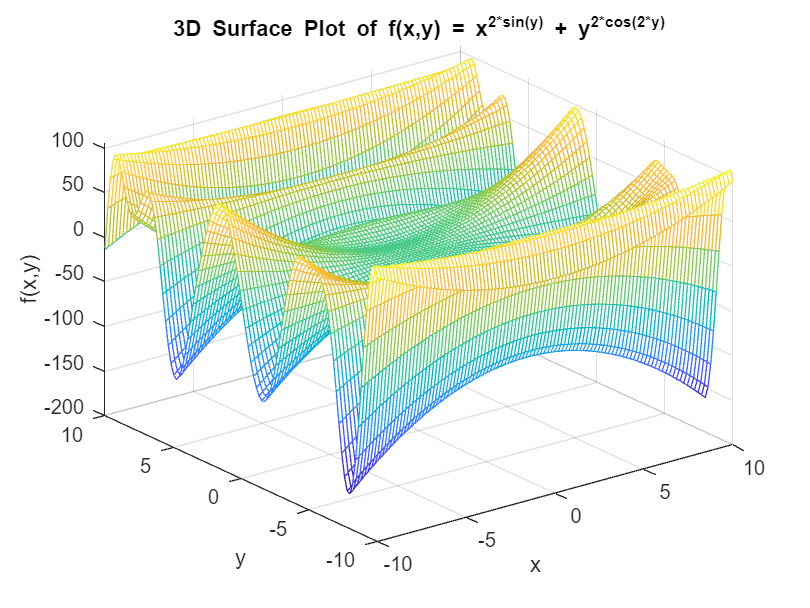

% 定義要繪製的函數
f = @(x, y) x.^2 .* sin(y) + y.^2 .* cos(2*y);

% 定義 x 和 y 的範圍
x = linspace(-10, 10, 100);  % x 的範圍和分辨率
y = linspace(-10, 10, 100);  % y 的範圍和分辨率

% 創建網格點
[X, Y] = meshgrid(x, y);

% 計算每個網格點上的函數值
Z = f(X, Y);

% 繪製三維曲面圖
figure;
mesh(X, Y, Z);
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('3D Surface Plot of f(x,y) = x^2*sin(y) + y^2*cos(2*y)');

12

n = 100; % 子區間數量
a = 1; % 積分下限
b = 2; % 積分上限

% 計算每個子區間的寬度
h = (b - a) / n;

% 使用左端點法計算近似積分
approx_integral = 0;
for i = 1:n
    % 計算左端點 x_i
    x_i = a + (i - 1) * h;
    
    % 計算函數值 f(x_i)
    f_x_i = cos(exp(-1/x_i)) / (x_i^2 + 1);
    
    % 將函數值乘以寬度 h 並加到近似積分結果中
    approx_integral = approx_integral + f_x_i * h;
end

% 顯示近似積分結果
disp(approx_integral);

    0.2852



13

syms x; % 定義符號變量 x
f = -5*x^6 - 4*x^5 - 6*x^4 + 5*x^3 + 4*x^2 - 4*x - 2; % 定義函數 f(x)
F = int(f, x); % 計算 f(x) 的不定積分

disp(F); % 顯示計算結果

$$-\frac{5\,x^{7}}{7}-\frac{2\,x^{6}}{3}-\frac{6\,x^{5}}{5}+\frac{5\,x^{4}}{4}+\frac{4\,x^{3}}{3}-2\,x^{2}-2\,x$$

14

syms x; % 定義符號變量 x
f = (3*x^4 - 2*x^3 + 5*x^2 - 7*x + 1) / (x^3 - x^2 + x - 1); % 定義函數 f(x)
partial_fraction = partfrac(f);
disp(partial_fraction); % 顯示偏分數分解的結果

$$3\,x+\frac{3\,x-2}{x^{2}+1}+1$$

15

syms x; % 定義符號變量 x
f = (x^2) + 2*sin(x) + (3*exp(x)) - (4*log(x)); % 定義要積分的函數 f(x)

integral_value = int(f, x); % 計算 f(x) 的不定積分

disp(integral_value); % 顯示積分的結果

$$4\,x-2\,\cos\left(x\right)+3\,{\mathrm{e}}^{x}-4\,x\,\log\left(x\right)+\frac{x^{3}}{3}$$

16

syms x y; % 定義符號變量 x 和 y
f = (x^4)*(y^3)*cos(x*y^2)*exp(-x^2*y^3); % 定義函數 f(x,y)

grad_f = gradient(f, [x, y]);
grad_f_eval = subs(grad_f, [x, y], [2, 1]);
disp(double(grad_f_eval)); % 將結果轉換為雙精度數字並顯示

   -0.0226
    0.0317



17

syms n;
N = 100; % 或者你想要的任何整數上限

f = @(n) 1 / ((2*n + 1) * (2*n + 3));
sum_an = symsum(f(n), n, 1, N);

sum_an_numeric = double(sum_an); % 將結果轉換為雙精度數字
disp(sum_an_numeric); % 顯示計算結果

    0.1642



18

% 定義曲線 y = sqrt(x^2 + 1) 和其導數 dy/dx
y = @(x) sqrt(x.^2 + 1);
dy_dx = @(x) x ./ sqrt(x.^2 + 1);

% 計算曲面積分
a = 2;
b = 3;
S = 2*pi*integral(@(x) y(x) .* sqrt(1 + (dy_dx(x)).^2), a, b);

% 輸出結果
disp(['旋轉曲面的面積 S = ', num2str(S)]);

旋轉曲面的面積 S = 23.0967


19

% 定義兩條曲線的方程式
f = @(x) x.^3 + 2*x.^2 - 3*x + 1;
g = @(x) x.^2 + 2*x + 1;

% 計算面積
a = 2;
b = 3;
area = integral(@(x) abs(f(x) - g(x)), a, b);

% 輸出結果
disp(['兩曲線之間的面積為: ', num2str(area)]);

兩曲線之間的面積為: 10.0833


20

syms x y;

% 定義函數 f(x,y)
f = x * cos(x*y) * exp(-x^2);

% 計算偏導數 df/dx
df_dx = diff(f, x);

% 計算偏導數 df/dy
df_dy = diff(f, y);

% 輸出結果
disp('偏導數 df/dx:');

偏導數 df/dx:


disp(df_dx);

$${\mathrm{e}}^{-x^{2}}\,\cos\left(x\,y\right)-2\,x^{2}\,{\mathrm{e}}^{-x^{2}}\,\cos\left(x\,y\right)-x\,y\,{\mathrm{e}}^{-x^{2}}\,\sin\left(x\,y\right)$$


disp('偏導數 df/dy:');

偏導數 df/dy:


disp(df_dy);

$$-x^{2}\,{\mathrm{e}}^{-x^{2}}\,\sin\left(x\,y\right)$$